# Plotter

Paramètres 


clear all
close all

% === Paramètres ===
folder_event = 'event';
folder_classic = 'classic';
base_path = '~/mecanum/csv/';
ev = [0.85 0.1 0.1];  % Rouge classique
cl = [0.1 0.7 0.1];
pred = [0.1 0.7 0.4];
folders = {'classic', 'event','predictive'};
colors = {cl, ev, pred};  % Associer couleur à chaque folder
plot_gamma = true;

mode_plot = 'predictive'; % 'classic', 'event' or 'both'

% === Sélection des dossiers à tracer selon mode_plot ===
folder_indices = [];
switch mode_plot
    case 'classic'
        folder_indices = find(strcmp(folders, 'classic'));
    case 'predictive'
        folder='predictive'
        folder_indices = find(strcmp(folders, 'predictive'));
    case 'event'
        folder_indices = find(strcmp(folders, 'event'));
    case 'both'
        folder_indices = 1:length(folders);
end

folder = 'predictive'

### Trajectoires

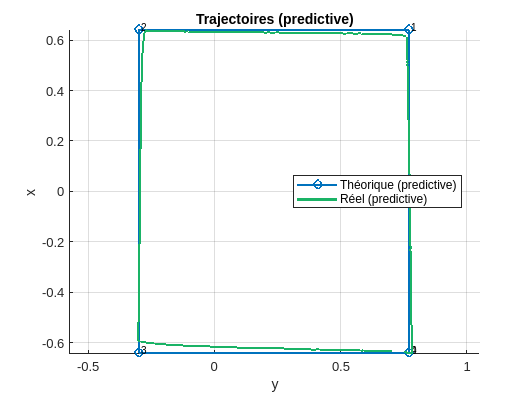

% === Figure ===
figure;
hold on; grid on; axis equal;
xlabel('y');
ylabel('x');
title(['Trajectoires (' mode_plot ')']);

% === Boucle sur les dossiers sélectionnés ===
for idx = folder_indices
    folder = folders{idx};
    color = colors{idx};
    
    % Lecture des CSV
    data_real = readtable(fullfile(base_path, folder, 'distributed_barycenter_logger.csv'));
    data_theory = readtable(fullfile(base_path, folder, 'distributed_goal_point_logger.csv'));

    % Données
    X_th = data_theory.x;
    Y_th = data_theory.y;
    x_real = data_real.x;
    y_real = data_real.y;

    % Tracé théorique
    plot(-Y_th, X_th, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, ...
        'DisplayName', ['Théorique (' folder ')']);
    for i = 1:length(X_th)
        text(-Y_th(i)+0.01, X_th(i)+0.01, num2str(i-1), 'FontSize', 8);
    end

    % Tracé réel
    plot(-y_real, x_real, '-', 'Color', color, 'LineWidth', 2, ...
        'DisplayName', ['Réel (' folder ')']);
    set(gcf,'Units','Inches');
    pos = get(gcf,'Position');
    
    % Facteurs de réduction (en proportion de la largeur/hauteur)
    scaleWidth = 0.85;   % réduction plus forte sur les côtés (10%)
    scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)
    
    % Calcul des nouvelles dimensions
    newWidth = pos(3) * scaleWidth;
    newHeight = pos(4) * scaleHeight;
    
    % Calcul des décalages pour centrer la nouvelle zone
    xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
    yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas
    
    % Appliquer la taille papier et la zone de découpe
    set(gcf,'PaperUnits','Inches');
    set(gcf,'PaperPositionMode','Manual');
    set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
    set(gcf,'PaperSize',[pos(3), pos(4)]);
    print(gcf,fullfile(base_path, folder, 'pic','trajectoires'),'-dpdf','-bestfit')

end

legend('Location', 'best');

Note : Dans le programme, on considère un point comme étant atteint si le barycentre de l'essaim est à 5cm de la cible, d'où les légers écarts avec les points-cibles.

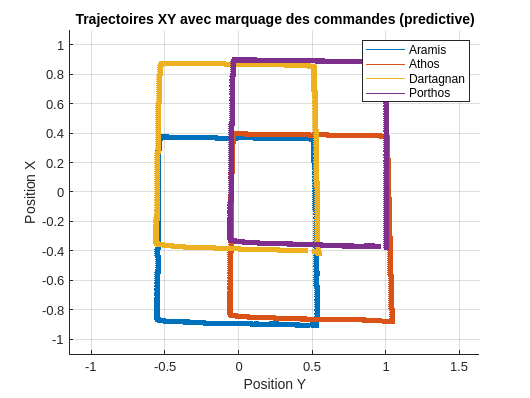

% === Figure ===
titles = {'Trajectoires XY avec marquage des commandes'};

legend_entries = {};
plot_handles = [];

% === Boucle sur les dossiers sélectionnés ===
for idx = folder_indices
    folder = folders{idx};
    files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));

    % Nouvelle figure à chaque dossier
    figure;
    hold on;
    axis equal;
    grid on;
    ylim([-1.1, 1.1]);  % Limites de l'axe Y
    xlabel('Position Y');
    ylabel('Position X');
    title([titles{1} ' (' folder ')']);

    % Couleurs pour les robots
    local_colors = lines(length(files));
    legend_entries = {};
    plot_handles = gobjects(length(files),1);

    for i = 1:length(files)
        filename = fullfile(base_path, folder, files(i).name);
        data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');

        % Extraire colonnes
        timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
        x = data{:,2};
        y = data{:,3};

        % Tracé
        plot_handles(i) = plot(-y, x, '-', 'Color', local_colors(i,:), 'LineWidth', 0.8);
        scatter(-y, x, 20, local_colors(i,:), 'filled', 'HandleVisibility', 'off');

        robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
        legend_entries{end+1} = robot_name;
    end

    legend(plot_handles, legend_entries, 'Location', 'northeast');
    % Récupérer la taille actuelle de la figure en pouces
    set(gcf,'Units','Inches');
    pos = get(gcf,'Position');
    
    % Facteurs de réduction (en proportion de la largeur/hauteur)
    scaleWidth = 0.90;   % réduction plus forte sur les côtés (10%)
    scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)
    
    % Calcul des nouvelles dimensions
    newWidth = pos(3) * scaleWidth;
    newHeight = pos(4) * scaleHeight;
    
    % Calcul des décalages pour centrer la nouvelle zone
    xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
    yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas
    
    % Appliquer la taille papier et la zone de découpe
    set(gcf,'PaperUnits','Inches');
    set(gcf,'PaperPositionMode','Manual');
    set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
    set(gcf,'PaperSize',[pos(3), pos(4)]);
    print(gcf,fullfile(base_path, folder, 'pic','trajectoires_marquage'),'-dpdf','-bestfit')

end

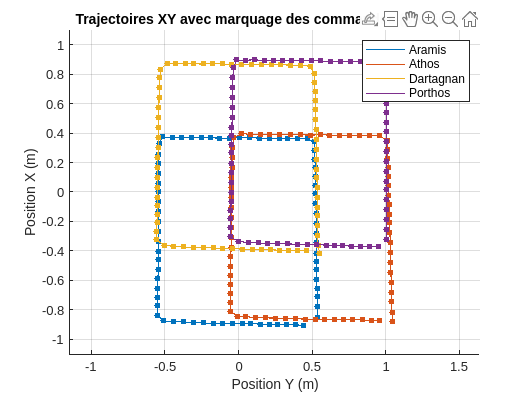

if strcmp(mode_plot, 'predictive')
    files = dir(fullfile(base_path, folder, '*_predictive_data.csv'));
    figure;
    hold on;
    axis equal;
    grid on;
    ylim([-1.1, 1.1]);
    xlabel('Position Y (m)');
    ylabel('Position X (m)');
    title([titles{1} ' (' folder ')']);

    local_colors = lines(length(files));
    legend_entries = {};
    plot_handles = gobjects(length(files),1);

    for i = 1:length(files)
        filename = fullfile(base_path, folder, files(i).name);
        data = readtable(filename, 'ReadVariableNames', true, 'Delimiter', ',');

        % Extraction des positions
        x = data.pos_x;
        y = data.pos_y;

        % Tracé : ROS-style (-y, x)
        plot_handles(i) = plot(-y, x, '-', 'Color', local_colors(i,:), 'LineWidth', 0.8);
        scatter(-y, x, 20, local_colors(i,:), 'filled', 'HandleVisibility', 'off');

        robot_name = extractBefore(files(i).name, '_predictive_data.csv');
        legend_entries{end+1} = robot_name;
    end

    legend(plot_handles, legend_entries);
    % Récupérer la taille actuelle de la figure en pouces
    set(gcf,'Units','Inches');
    pos = get(gcf,'Position');
    
    % Facteurs de réduction (en proportion de la largeur/hauteur)
    scaleWidth = 0.90;   % réduction plus forte sur les côtés (10%)
    scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)
    
    % Calcul des nouvelles dimensions
    newWidth = pos(3) * scaleWidth;
    newHeight = pos(4) * scaleHeight;
    
    % Calcul des décalages pour centrer la nouvelle zone
    xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
    yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas
    
    % Appliquer la taille papier et la zone de découpe
    set(gcf,'PaperUnits','Inches');
    set(gcf,'PaperPositionMode','Manual');
    set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
    set(gcf,'PaperSize',[pos(3), pos(4)]);
    print(gcf,fullfile(base_path, folder, 'pic','true_trajectoires_marquage'),'-dpdf','-bestfit')
end

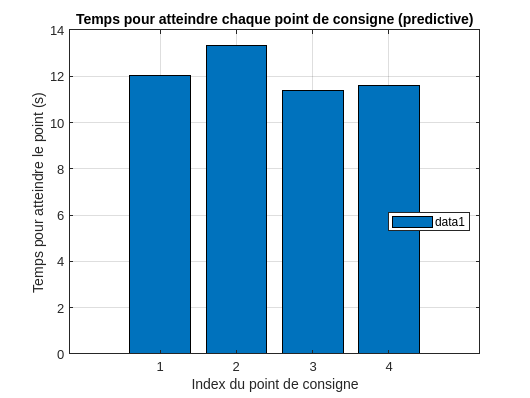

for idx = folder_indices
    folder = folders{idx};
    
    % === Lecture CSV ===
    fichier_distance = fullfile(base_path, folder, 'distributed_distance_logger.csv');
    fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');
    
    data = readtable(fichier_distance);
    traj = readtable(fichier_trajectoire);

    time_abs = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    time = seconds(time_abs - time_abs(1));
    time_goal = seconds(datetime(traj{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs(1));
    
    % Calcul des délais
    delays = diff(time_goal);
    n = length(delays);
    delays = delays(1:n);
    
    % === Barplot ===
    figure;
    b = bar([delays], 'grouped');
    xlabel('Index du point de consigne');
    ylabel('Temps pour atteindre le point (s)');
    title(['Temps pour atteindre chaque point de consigne (' folder ')']);
    legend('Location', 'best');
    grid on;
end

### Distances

Ligne grise verticale : envoi d'un nouveau point-destination.

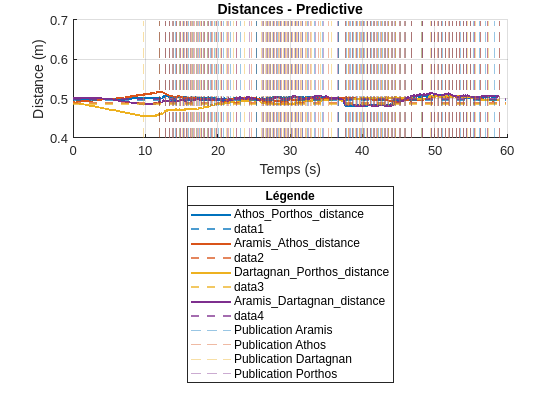

% === Lecture conditionnelle des données ===

fichier_distance_classic = fullfile(base_path, 'classic', 'distributed_distance_logger.csv');
fichier_trajectoire_classic = fullfile(base_path, 'classic', 'distributed_goal_point_logger.csv');
data_classic = readtable(fichier_distance_classic);
traj_classic = readtable(fichier_trajectoire_classic);
time_abs_classic = datetime(data_classic{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
time_classic = seconds(time_abs_classic - time_abs_classic(1));
time_goal_classic = seconds(datetime(traj_classic{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs_classic(1));

% Lecture données event si besoin
if strcmp(mode_plot, 'event') || strcmp(mode_plot, 'both')
    fichier_distance_event = fullfile(base_path, 'event', 'distributed_distance_logger.csv');
    fichier_trajectoire_event = fullfile(base_path, 'event', 'distributed_goal_point_logger.csv');
    data_event = readtable(fichier_distance_event);
    traj_event = readtable(fichier_trajectoire_event);
    time_abs_event = datetime(data_event{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    time_event = seconds(time_abs_event - time_abs_event(1));
    time_goal_event = seconds(datetime(traj_event{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs_event(1));
end

if strcmp(mode_plot, 'predictive') 
    fichier_distance_predictive = fullfile(base_path, 'predictive', 'distributed_distance_logger.csv');
    fichier_trajectoire_predictive = fullfile(base_path, 'predictive', 'distributed_goal_point_logger.csv');
    data_predictive = readtable(fichier_distance_predictive);
    traj_predictive = readtable(fichier_trajectoire_predictive);
    time_abs_predictive = datetime(data_predictive{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    time_predictive = seconds(time_abs_predictive - time_abs_predictive(1));
    time_goal_predictive = seconds(datetime(traj_predictive{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS') - time_abs_predictive(1));
end

% === Couleurs cohérentes ===
colors = lines(width(data_classic)-1);  % même jeu de couleurs pour tous

% === Création du layout ===
if strcmp(mode_plot, 'both')
    t = tiledlayout(2, 1);
elseif strcmp(mode_plot, 'classic') || strcmp(mode_plot, 'event') || strcmp(mode_plot, 'predictive')
    t = tiledlayout(1, 1);
end
t.TileSpacing = 'compact';
t.Padding = 'compact';

legend_handles = [];
legend_names = {};  % noms pour la légende

% === CLASSIC ===
if strcmp(mode_plot, 'classic') || strcmp(mode_plot, 'both')
    ax1 = nexttile;
    axes(ax1); hold on; grid on;

    for i = 2:width(data_classic)
        name = data_classic.Properties.VariableNames{i};
        display_name = strrep(name, '_', '\_');
        legend_names{end+1} = display_name;

        legend_handles(i-1) = plot(time_classic, data_classic{:,i}, ...
            'Color', colors(i-1,:), ...
            'DisplayName', display_name, ...
            'LineWidth', 1.5);

        yline(data_classic{1,i}, '--', 'Color', colors(i-1,:), 'LineWidth', 1.5);
    end

    for i = 2:length(time_goal_classic)
        xline(time_goal_classic(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
    end

    title('Distances - Classique');
    xlabel('Temps (s)');
    ylabel('Distance (m)');
    ylim([0.4, 0.8])
end

% === EVENT ===
if strcmp(mode_plot, 'event') || strcmp(mode_plot, 'both')
    if strcmp(mode_plot, 'both')
        ax2 = nexttile;
    else
        ax2 = gca;
    end
    axes(ax2); hold on; grid on;
    if ~strcmp(mode_plot, 'both')
        legend_names = {}; % (Réinitialise, par sécurité)
        for i = 2:width(data_event)
            name = data_event.Properties.VariableNames{i};
            display_name = strrep(name, '_', '\_');
            legend_names{end+1} = display_name;
        end
    end
    for i = 2:width(data_event)
        plot(time_event, data_event{:,i}, ...
            'Color', colors(i-1,:), ...
            'DisplayName', legend_names{i-1}, ...
            'LineWidth', 1.5);
        %yline(data_event{1,i}, '--', 'Color', colors(i-1,:), 'LineWidth', 1.5,'HandleVisibility', 'off');
    end

    for i = 2:length(time_goal_event)
        xline(time_goal_event(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
    end

    title('Distances - Event');
    xlabel('Temps (s)');
    ylabel('Distance (m)');
    ylim([0.4, 0.8])
end

% == Predictive ==

if strcmp(mode_plot, 'predictive') 
    ax2 = gca;
    axes(ax2); hold on; grid on;

    % Tracé des distances 
    legend_names = {};  
    for i = 2:width(data_predictive)
        name = data_predictive.Properties.VariableNames{i};
        display_name = strrep(name, '_', '\_');
        legend_names{end+1} = display_name;

        plot(time_predictive, data_predictive{:,i}, ...
            'Color', colors(i-1,:), ...
            'DisplayName', display_name, ...
            'LineWidth', 1.5);

        yline(data_predictive{1,i}, '--', 'Color', colors(i-1,:), 'LineWidth', 1.5);
    end

    for i = 2:length(time_goal_predictive)
        xline(time_goal_predictive(i), 'k--', 'LineWidth', 1.2, 'Alpha', 0.4, 'HandleVisibility', 'off');
    end

    % Définir time_start une fois
    time_start = datetime(data_predictive{1,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

    predictive_folder = fullfile(base_path, 'predictive');
    files = dir(fullfile(predictive_folder, '*_predictive_data.csv'));

    % Palette de couleurs pour différencier les robots
    local_colors = lines(length(files));

    for i = 1:length(files)
        filename = fullfile(predictive_folder, files(i).name);
        data = readtable(filename, 'ReadVariableNames', true, 'Delimiter', ',');

        % Lire tous les timestamps
        timestamps_str = data.timestamp;
        timestamps = datetime(timestamps_str, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

        % Temps relatif depuis le début
        relative_times = seconds(timestamps - time_start);

        % Extraire le nom du robot à partir du nom de fichier
        [~, name_only, ~] = fileparts(files(i).name);
        robot_name = strrep(name_only, '_predictive_data', '');
        display_name = ['Publication ', strrep(robot_name, '_', '\_')];

        % Tracer les lignes verticales pour ce robot
        for t = 1:length(relative_times)
            if t == 1
                xline(relative_times(t), '--', 'Color', local_colors(i,:), ...
                    'Alpha', 0.4, 'LineWidth', 1.2, ...
                    'DisplayName', display_name);
            else
                xline(relative_times(t), '--', 'Color', local_colors(i,:), ...
                    'Alpha', 0.4, 'LineWidth', 1.2, ...
                    'HandleVisibility', 'off');
            end
        end
    end

    title('Distances - Predictive');
    xlabel('Temps (s)');
    ylabel('Distance (m)');
    legend('Location', 'southoutside', 'Orientation', 'vertical');
    ylim([0.4, 0.7])
end


% === LÉGENDE ===
if strcmp(mode_plot, 'both')
    % Figure séparée pour la légende
    fig_leg = figure('Name', 'Légende Distances Inter-Robots');
    ax_leg = axes('Parent', fig_leg, 'Visible', 'off'); hold on;
    h_dummy = gobjects(length(legend_names), 1);

    for i = 1:length(legend_names)
        h_dummy(i) = plot(ax_leg, NaN, NaN, '-', ...
            'Color', colors(i,:), ...
            'DisplayName', legend_names{i}, ...
            'LineWidth', 1.5);
    end

    legend(ax_leg, h_dummy, 'Orientation', 'vertical', 'Location', 'northoutside');
    title('Distances inter-robots');
elseif strcmp(mode_plot, 'predictive')
    lgd = legend(legend_handles, 'Orientation', 'vertical', 'Location', 'southoutside');
    lgd.Title.String = 'Légende';
else
    % Sinon, légende dans la figure principale
    lgd = legend(legend_handles, 'Orientation', 'vertical', 'Location', 'southoutside');
    lgd.Title.String = 'Distances inter-robots';
end

% Récupérer la taille actuelle de la figure en pouces
set(gcf,'Units','Inches');
pos = get(gcf,'Position');

% Facteurs de réduction (en proportion de la largeur/hauteur)
scaleWidth = 0.90;   % réduction plus forte sur les côtés (10%)
scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)

% Calcul des nouvelles dimensions
newWidth = pos(3) * scaleWidth;
newHeight = pos(4) * scaleHeight;

% Calcul des décalages pour centrer la nouvelle zone
xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas

% Appliquer la taille papier et la zone de découpe
set(gcf,'PaperUnits','Inches');
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
set(gcf,'PaperSize',[pos(3), pos(4)]);
print(gcf,fullfile(base_path, folder, 'pic','distance'),'-dpdf','-bestfit')

On note que les distances varient au lancement de l'algorithme, puis les robots convergent vers leurs positions voulues dans la formation (distance inter-robot relativement constante après que le premier point soit atteint)

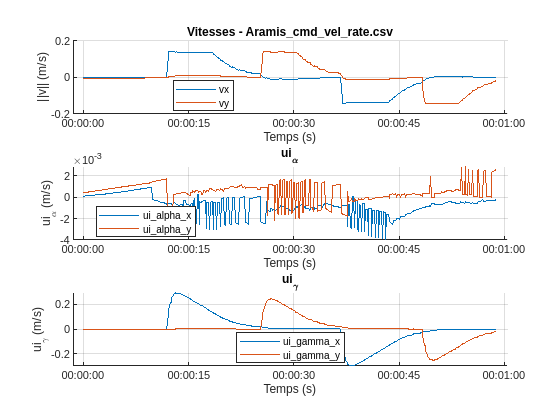

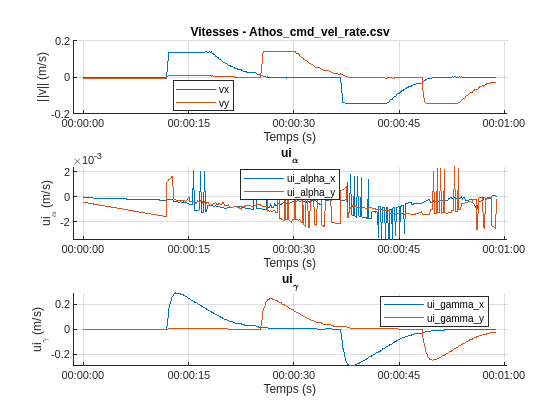

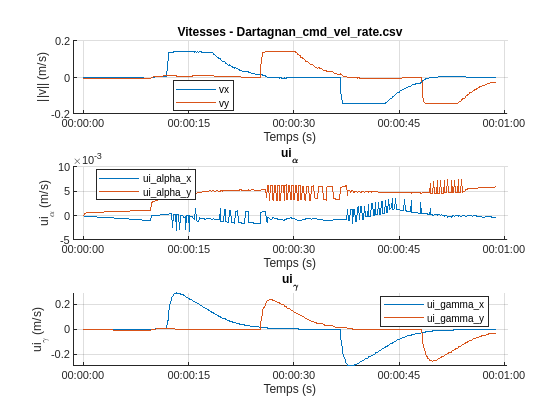

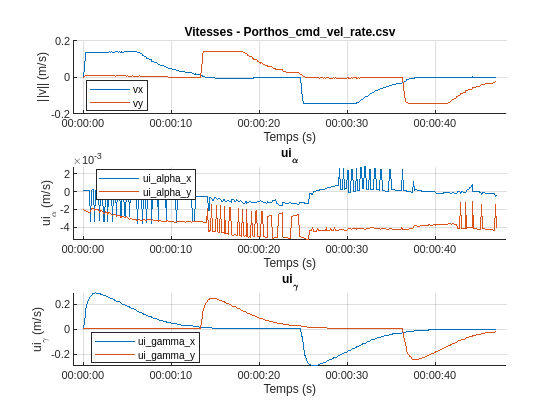

if plot_gamma
    for idx = folder_indices
        folder = folders{idx};
        files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));

        for f = 1:length(files)
            filepath = fullfile(files(f).folder, files(f).name);
            data = readtable(filepath);

            % Extraire colonnes
            t = data.timestamp - data.timestamp(1);
            vx = data.linear_x;
            vy = data.linear_y;
            ui_gamma_x = data.ui_gamma_x;
            ui_gamma_y = data.ui_gamma_y;
            ui_alpha_x = data.ui_alpha_x;
            ui_alpha_y = data.ui_alpha_y;

            % Figure individuelle par fichier
            figure;
            
            % Subplot 1
            subplot(3,1,1);
            hold on;
            plot(t, vx, 'DisplayName', 'vx');
            plot(t, vy, 'DisplayName', 'vy');
            
            xlabel('Temps (s)');
            ylabel('||v|| (m/s)');
            title(['Vitesses - ' files(f).name],'Interpreter', 'none');
            legend('Location', 'best');
            grid on;

            % Subplot 2
            subplot(3,1,2);
            hold on;
            plot(t, ui_alpha_x, 'DisplayName', 'ui\_alpha\_x');
            plot(t, ui_alpha_y, 'DisplayName', 'ui\_alpha\_y');
            xlabel('Temps (s)');
            ylabel('ui_{\alpha} (m/s)');
            title('ui_{\alpha}');
            legend('Location', 'best');
            grid on;

            % Subplot 3
            subplot(3,1,3);
            hold on;
            plot(t, ui_gamma_x, 'DisplayName', 'ui\_gamma\_x');
            plot(t, ui_gamma_y, 'DisplayName', 'ui\_gamma\_y');
            xlabel('Temps (s)');
            ylabel('ui_{\gamma} (m/s)');
            title('ui_{\gamma}');
            legend('Location', 'best');
            grid on;
        end
    end
end

### Commandes

function plot_command_timestamps(base_path, folder, fichier_trajectoire)
    fprintf('--- Traitement dossier : %s ---\n', folder);

    % === Liste des fichiers csv commandes ===
    files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));

    robot_names = {};
    timestamp_counts = [];
    timestamp_data = containers.Map;
    dt_stats = containers.Map;

    % === Lecture fichiers commandes ===
    for i = 1:length(files)
        filename = fullfile(base_path, folder, files(i).name);
        data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');

        % Timestamps en datetime
        timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');

        % Nom robot
        robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');
        robot_names{end+1} = robot_name;

        % Temps relatif
        timestamps_rel = seconds(timestamps - timestamps(1));
        timestamp_data(robot_name) = timestamps_rel;
        timestamp_counts(end+1) = numel(timestamps_rel);

        % Statistiques delta t
        delta_t = seconds(diff(timestamps));
        stats.mean = mean(delta_t);
        stats.std = std(delta_t);
        stats.min = min(delta_t);
        stats.max = max(delta_t);
        dt_stats(robot_name) = stats;

        % Affichage console
        fprintf('\nRobot: %s\n', robot_name);
        fprintf('  N = %d commandes\n', numel(timestamps));
        fprintf('  Δt moyen    : %.4f s\n', stats.mean);
        fprintf('  Δt min      : %.4f s\n', stats.min);
        fprintf('  Δt max      : %.4f s\n', stats.max);
        fprintf('  Δt ec type  : %.4f s\n', stats.std);
    end

    % === Figure 1 : Histogramme commandes ===
    figure('Name', ['Histogramme commandes - ' folder]);
    bar(categorical(robot_names), timestamp_counts);
    xlabel('Nom du robot');
    ylabel('Nombre de commandes');
    title(['Nombre de commandes par robot (' folder ')']);
    grid on;

    % === Lecture des points de trajectoire ===
    traj_data = readtable(fichier_trajectoire, 'Delimiter', ',', 'ReadVariableNames', true);
    raw_timestamps = traj_data{:, 1};
    goal_times = datetime(raw_timestamps, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    goal_times_rel = seconds(goal_times - goal_times(1));

    % === Figure 2 : Chronogrammes synchronisés ===
    figure('Name', ['Chronogrammes commandes - ' folder]);
    n = length(robot_names);

    % Fusionner tous les temps relatifs
    all_times = [];
    for i = 1:n
        all_times = [all_times; timestamp_data(robot_names{i})];
    end
    all_times = unique(all_times);

    for i = 1:n
        ax = subplot(n, 1, i);
        timestamps = timestamp_data(robot_names{i});
        y = ismember(all_times, timestamps);
        stem(all_times, y, 'Marker', 'none', 'LineWidth', 1.2);
        ylim([-0.1, 1.1]);
        ylabel(robot_names{i});
        if i == 1
            title(['Chronogrammes des commandes (' folder ')']);
        end
        if i < n
            set(gca, 'XTickLabel', []);
        else
            xlabel('Temps (s)');
        end

        % Lignes verticales des changements de consigne
        hold on;
        for t = goal_times_rel'
            xline(t, '--r', 'LineWidth', 1);
        end
    end
    
end

function compare_command_timestamps(base_path, folders)
    % === Initialisation ===
    robot_names = [];
    data_map = containers.Map;
    timestamp_counts = containers.Map;
    dt_means = containers.Map;
    dt_stds = containers.Map;
    timestamp_data = containers.Map;

    % === Lecture des données pour chaque dossier ===
    for f = 1:length(folders)
        folder = folders{f};
        files = dir(fullfile(base_path, folder, '*_cmd_vel_rate.csv'));
        
        for i = 1:length(files)
            filename = fullfile(base_path, folder, files(i).name);
            data = readtable(filename, 'ReadVariableNames', false, 'Delimiter', ',');
            timestamps = datetime(data{:,1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
            robot_name = extractBefore(files(i).name, '_cmd_vel_rate.csv');

            if ~ismember(robot_name, robot_names)
                robot_names{end+1} = robot_name; %#ok<AGROW>
            end

            key = [folder '_' robot_name];
            timestamps_rel = seconds(timestamps - timestamps(1));
            timestamp_data(key) = timestamps_rel;
            timestamp_counts(key) = numel(timestamps_rel);
            delta_t = seconds(diff(timestamps));
            dt_means(key) = mean(delta_t);
            dt_stds(key) = std(delta_t);
        end
    end

    % === Bar chart : nombre de commandes par robot ===
    figure('Name', 'Nombre de commandes par robot'); hold on;
    bar_data = zeros(length(robot_names), length(folders));
    for r = 1:length(robot_names)
        for f = 1:length(folders)
            key = [folders{f} '_' robot_names{r}];
            if isKey(timestamp_counts, key)
                bar_data(r,f) = timestamp_counts(key);
            else
                bar_data(r,f) = NaN;
            end
        end
    end
    bar(categorical(robot_names), bar_data);
    legend(folders, 'Location', 'northoutside', 'Orientation', 'horizontal');
    ylabel('Nombre de commandes');
    title('Comparaison du nombre de commandes');
    grid on;

    % === Moyennes des delta_t ===
    figure('Name', 'Moyenne du Δt des commandes'); hold on;
    dt_mean_data = zeros(length(robot_names), length(folders));
    for r = 1:length(robot_names)
        for f = 1:length(folders)
            key = [folders{f} '_' robot_names{r}];
            if isKey(dt_means, key)
                dt_mean_data(r,f) = dt_means(key);
            else
                dt_mean_data(r,f) = NaN;
            end
        end
    end
    bar(categorical(robot_names), dt_mean_data);
    legend(folders, 'Location', 'northoutside', 'Orientation', 'horizontal');
    ylabel('Moyenne de Δt (s)');
    title('Comparaison du Δt moyen entre classic et event');
    grid on;

    % === Std des delta_t ===
    figure('Name', 'Ecart-type du Δt des commandes'); hold on;
    dt_std_data = zeros(length(robot_names), length(folders));
    for r = 1:length(robot_names)
        for f = 1:length(folders)
            key = [folders{f} '_' robot_names{r}];
            if isKey(dt_stds, key)
                dt_std_data(r,f) = dt_stds(key);
            else
                dt_std_data(r,f) = NaN;
            end
        end
    end
    bar(categorical(robot_names), dt_std_data);
    legend(folders, 'Location', 'northoutside', 'Orientation', 'horizontal');
    ylabel('Ecart-type de Δt (s)');
    title('Comparaison de la variabilité du Δt entre classic et event');
    grid on;

    % === Chronogrammes avec 2 subplots par robot ===
for r = 1:length(robot_names)
    robot = robot_names{r};
    figure('Name', ['Chronogrammes séparés - ' robot]);
    
    % Subplot 1 : classic
    subplot(2,1,1); hold on; grid on;
    if isKey(timestamp_data, ['classic_' robot])
        t_rel = timestamp_data(['classic_' robot]);
        stem(t_rel, ones(size(t_rel)), 'r', 'DisplayName', 'classic', 'LineWidth', 1.3);
    end
    title(['Chronogramme commandes - classic - ' robot]);
    xlabel('Temps (s)');
    ylim([0 1.5]);
    yticks([]);
    legend('Location', 'best');
    
    % Subplot 2 : event
    subplot(2,1,2); hold on; grid on;
    if isKey(timestamp_data, ['event_' robot])
        t_rel = timestamp_data(['event_' robot]);
        stem(t_rel, ones(size(t_rel)), 'b', 'DisplayName', 'event', 'LineWidth', 1.3);
    end
    title(['Chronogramme commandes - event - ' robot]);
    xlabel('Temps (s)');
    ylim([0 1.5]);
    yticks([]);
    legend('Location', 'best');

end
end

switch mode_plot
    case 'classic'
        folder = 'classic';
        fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');
        plot_command_timestamps(base_path, folder, fichier_trajectoire);

    case 'event'
        folder = 'event';
        fichier_trajectoire = fullfile(base_path, folder, 'distributed_goal_point_logger.csv');
        plot_command_timestamps(base_path, folder, fichier_trajectoire);
            % Récupérer la taille actuelle de la figure en pouces
    set(gcf,'Units','Inches');
    pos = get(gcf,'Position');
    
    % Facteurs de réduction (en proportion de la largeur/hauteur)
    scaleWidth = 0.90;   % réduction plus forte sur les côtés (10%)
    scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)
    
    % Calcul des nouvelles dimensions
    newWidth = pos(3) * scaleWidth;
    newHeight = pos(4) * scaleHeight;
    
    % Calcul des décalages pour centrer la nouvelle zone
    xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
    yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas
    
    % Appliquer la taille papier et la zone de découpe
    set(gcf,'PaperUnits','Inches');
    set(gcf,'PaperPositionMode','Manual');
    set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
    set(gcf,'PaperSize',[pos(3), pos(4)]);
    print(gcf,fullfile(base_path, folder, 'pic','chronogramme'),'-dpdf','-bestfit')

    case 'both'
        compare_command_timestamps(base_path, folders);  % comparaison directe
    
    case 'predictive'
        predictive_folder = fullfile(base_path, 'predictive');
        files = dir(fullfile(predictive_folder, '*_predictive_data.csv'));
        
        robot_names = strings(length(files),1);
        counts = zeros(length(files),1);
        
        for i = 1:length(files)
            filename = fullfile(predictive_folder, files(i).name);
            data = readtable(filename, 'ReadVariableNames', true, 'Delimiter', ',');
        
            % Filtrer les lignes avec event_type == 'position_published'
            idx_pos_pub = strcmp(data.event_type, 'position_published');
        
            % Stocker le nom robot (extraction avant _predictive_data.csv)
            [~, name, ~] = fileparts(files(i).name);
            robot_name = extractBefore(name, '_predictive_data');
            robot_names(i) = robot_name;
        
            % Compter le nombre de position_published
            counts(i) = sum(idx_pos_pub);
        end
        
        % Tracé du diagramme en barres
        figure;
        bar(counts);
        set(gca, 'XTickLabel', robot_names, 'XTick', 1:length(files));
        xlabel('Robot');
        ylabel('Nombre de position publiée');
        title('Nombre total de position\_published par robot');
        grid on;
        xtickangle(45); % rotation des labels si besoin

end

Error using  .  (line 229)
Unrecognized table variable name 'event_type'.

dataDir = fullfile(base_path, folder,'cpu_ram');

%--- Recherche de tous les fichiers CPU pour extraire les robots --------
cpuFiles = dir(fullfile(dataDir, '*_cpu_usage.csv'));
robotNames = cell(numel(cpuFiles),1);
for k = 1:numel(cpuFiles)
    fname = cpuFiles(k).name;
    % on retire le suffixe '_cpu_usage.csv'
    robotNames{k} = erase(fname, '_cpu_usage.csv');
end
robotNames = unique(robotNames);

%--- Préparation de la figure ------------------------------------------
nBots = numel(robotNames);
nCols = ceil(sqrt(nBots));
nRows = ceil(nBots/nCols);
figure('Color','w','Position',[100 100 1200 800]);

%--- Figure CPU/RAM en pourcentage -------------------------------------
figure('Color','w','Position',[100 100 1200 800]);

for i = 1:nBots
    robot = robotNames{i};

    cpuFile  = fullfile(dataDir, [robot '_cpu_usage.csv']);
    ramFile  = fullfile(dataDir, [robot '_ram_usage.csv']);
    
    Tcpu = readtable(cpuFile);
    Tram = readtable(ramFile);
    
    dt_cpu = datetime(Tcpu.timestamp, 'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    dt_ram = datetime(Tram.timestamp, 'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    
    t0 = min([dt_cpu(1), dt_ram(1)]);
    x_cpu = seconds(dt_cpu - t0);
    x_ram = seconds(dt_ram - t0);
    
    subplot(nRows, nCols, i);
    hold on;
    plot(x_cpu, Tcpu.cpu_percent, 'LineWidth',1.5);
    plot(x_ram, Tram.ram_percent, 'LineWidth',1.5);
    hold off;
    
    xlabel('Temps (s)');
    ylabel('Pourcentage (%)');
    title(sprintf('Robot: %s', robot), 'Interpreter','none');
    legend({'CPU','RAM'}, 'Location','best');
    grid on;
end
% Récupérer la taille actuelle de la figure en pouces
set(gcf,'Units','Inches');
pos = get(gcf,'Position');

% Facteurs de réduction (en proportion de la largeur/hauteur)
scaleWidth = 0.90;   % réduction plus forte sur les côtés (10%)
scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)

% Calcul des nouvelles dimensions
newWidth = pos(3) * scaleWidth;
newHeight = pos(4) * scaleHeight;

% Calcul des décalages pour centrer la nouvelle zone
xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas

% Appliquer la taille papier et la zone de découpe
set(gcf,'PaperUnits','Inches');
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
set(gcf,'PaperSize',[pos(3), pos(4)]);
print(gcf,fullfile(base_path, folder, 'pic','cpu_ram'),'-dpdf','-bestfit')

%--- Figure RAM utilisée en Mo -----------------------------------------
figure('Color','w','Position',[100 100 1200 800]);
for i = 1:nBots
    robot = robotNames{i};
    usedFile = fullfile(dataDir, [robot '_ram_used.csv']);
    
    Tuse = readtable(usedFile);
    dt_use = datetime(Tuse.timestamp,'InputFormat','yyyy-MM-dd''T''HH:mm:ss.SSSSSS');
    t0 = dt_use(1);
    x_use = seconds(dt_use - t0);
    
    subplot(nRows, nCols, i);
    plot(x_use, Tuse.ram_used_mb, 'LineWidth',1.5);
    
    xlabel('Temps (s)');
    ylabel('RAM utilisée (Mo)');
    title(sprintf('Robot: %s', robot), 'Interpreter','none');
    grid on;

        % Récupérer la taille actuelle de la figure en pouces
    set(gcf,'Units','Inches');
    pos = get(gcf,'Position');
    
    % Facteurs de réduction (en proportion de la largeur/hauteur)
    scaleWidth = 0.90;   % réduction plus forte sur les côtés (10%)
    scaleHeight = 0.95;  % réduction légère en haut et en bas (5%)
    
    % Calcul des nouvelles dimensions
    newWidth = pos(3) * scaleWidth;
    newHeight = pos(4) * scaleHeight;
    
    % Calcul des décalages pour centrer la nouvelle zone
    xOffset = (pos(3) - newWidth) / 2;  % coupe plus à gauche et droite
    yOffset = (pos(4) - newHeight) / 2; % coupe un peu en haut et bas
    
    % Appliquer la taille papier et la zone de découpe
    set(gcf,'PaperUnits','Inches');
    set(gcf,'PaperPositionMode','Manual');
    set(gcf,'PaperPosition',[xOffset, yOffset, newWidth, newHeight]);
    set(gcf,'PaperSize',[pos(3), pos(4)]);
    print(gcf,fullfile(base_path, folder, 'pic','ram_used'),'-dpdf','-bestfit')

end
